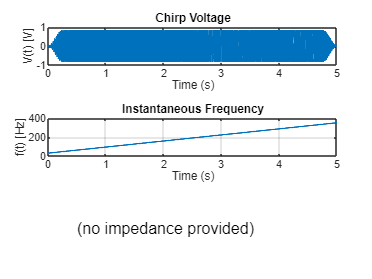

Fs= 10000;
y = outputVec{1};

[c, t] = chirpWithEnvelope(30, 350, 0.8, 5, 10000);

y = lowpass(y, 1000, Fs);
y = y - mean(y);
y = y';

order = 500;
cuttoffFreq = 100/(5000/2);
b = fir1(order, cuttoffFreq, 'high');
y = filter(b, 1, y);
pos = cumsum(y);





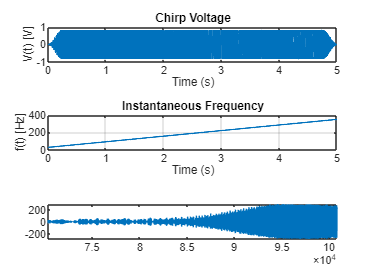

 plot(y);
 f = fliplr(c);
 plot(c);

 plot(f, 'r');
 hrec = conv(f, y);
 plot(hrec);
 xlim([70334 100821]);

 epsilon_min = 1e-6;
 epsilon_max = 1e3;
 epsilonVec = zeros(1, length(freq));

Unrecognized function or variable 'freq'.

 deltaf = 5;
 for j = 1:length(freq)
     f = freq(j);
     if f < fmin-deltaf
        epsilonVec(j) = epsilon_max;
     elseif f >=fmin-deltaf && f<=fmin+deltaf
        epsilonVec(j) = epsilon_max - (f-(fmin-deltaf))/(2*deltaf)*(epsilon_max - epsilon_min);
     elseif f >= fmin + deltaf && f <= fmax-deltaf
        epsilonVec(j) = epsilon_min;
     elseif f > fmax-deltaf && f <= fmax+deltaf
        epsilonVec(j) = epsilon_min + (f-(fmax-deltaf))/(2*deltaf)*(epsilon_max - epsilon_min);
     else
        epsilonVec(j) = epsilon_max;
     end  
 end

 plot(freq, epsilonVec);
 xlim([0 700]);

  Cpack = conj(hrec)./(abs(hrec).^2+epsilonVec);

Unrecognized function or variable 'Hrec'.

  plot(freq, abs(Cpack));
  cpack = ifft(Cpack, 'symmetric');
  plot(cpack)

packedImpulse = conv(hrec, cpack);

Unrecognized function or variable 'cpack'.

packedImpulse = packedImpulse(1:length(hrec));
plot(packedImpulse, 'r')

function spec(x, Fs)
    window = hamming(256);
    noverlap = 255;
    nfft = 4096;
    spectrogram(x, window, noverlap, nfft, Fs);
    ylabel('Time (s)');
    xlabel('Frequency (Hz)');
    colormap("parula");
    colorbar;
end

spec(packedImpulse, Fs)

Hpacked = fft(packedImpulse);
freqSS = linspace(0, Fs/2, nfft/2+1);
HpackedSS = Hpacked(1:floor(nfft/2)+1);
plot(freqSS, abs(HpackedSS).^2);
plot(freq, abs(Hpacked).^2)